
[r,fs]= audioread('newwav.wav')

r =     1.0000
    1.0000
    0.0859
   -1.0000
   -0.7423
   -1.0000
    1.0000
   -0.6156
    0.7480
   -0.1924


fs = 4000

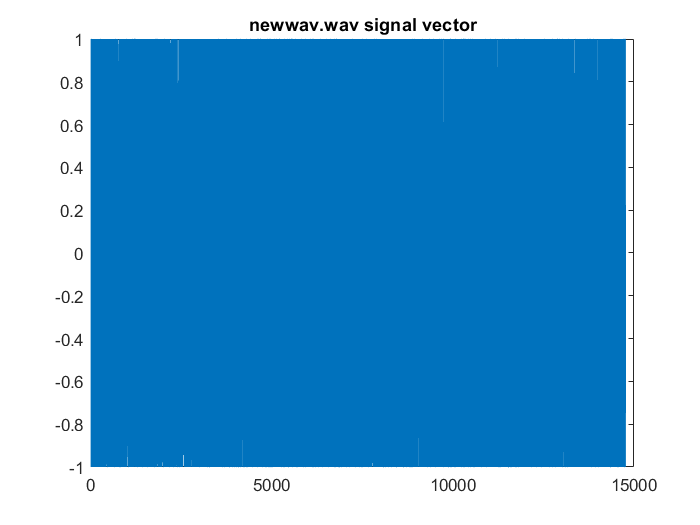


%Maximillian Obasiolu...
...EE 432 Lab 10
    
%ee432 FSK lab
Tb = 0.1; %bit period 
Ns = fs*Tb; % 4000 samples/sec * 0.1 sec/bit = 400 samples per bit
fc = 500; %center frequency
df = 10; %frequency deviation of 10 
x = linspace(0,Tb,Ns);
f0 = fc-df;
f1 = fc+df;
s0 = sin(2*pi*f0*x);
s1 = sin(2*pi*f1*x);
%synch = [ s0 s1 s0 s1 s0 s1 s0 s1 ];
%data = [ s0 s0 s1 s0 s1 s1 s0 s1 s0 s1 s1 s1 s1 s0 s1 s0 ];
%z = [ synch data ];
%sound(r,fs); 
plot(r)
title('newwav.wav signal vector')

r has an unknown amount of synch bits and data bits, which is why we have to process it


%Matched Filter Design & Envelope Detector for s0
x_0 = conv(r,s0)*(2/Ns)

x_0 =          0
    0.0035
    0.0085
    0.0090
    0.0009
   -0.0103
   -0.0191
   -0.0136
   -0.0026
    0.0125


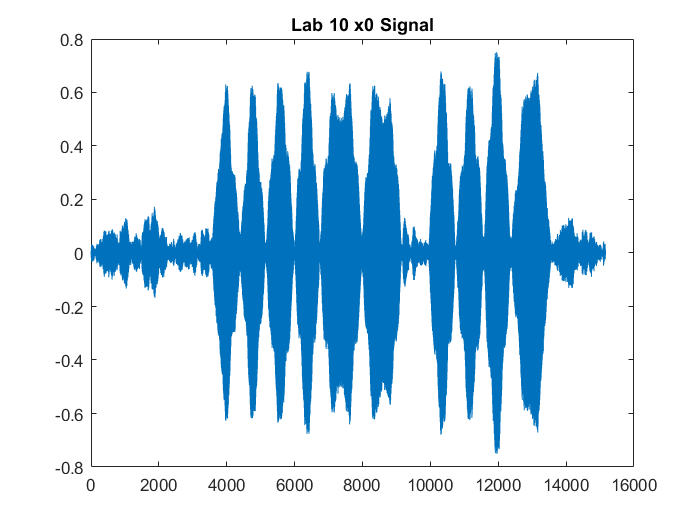

plot(x_0) %matched filter output
title('Lab 10 x0 Signal')

Ts = (Tb/Ns) % sample period

Ts = 2.5000e-04

%Envelope Detector 1:
y_0 = abs(x_0) %Rectify

y_0 =          0
    0.0035
    0.0085
    0.0090
    0.0009
    0.0103
    0.0191
    0.0136
    0.0026
    0.0125


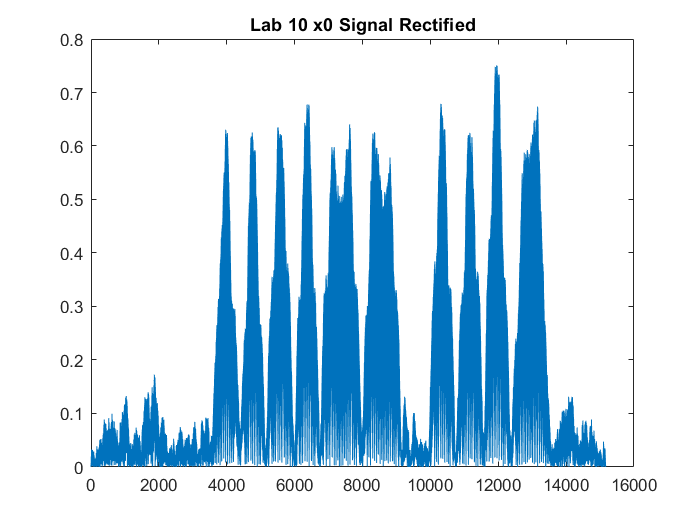

plot(y_0) %gives us positive half of matched filter output
title('Lab 10 x0 Signal Rectified')

%Lowpass Filter
b_0 = conv(y_0, ones(1,Ns))*(2/Ns)

b_0 =          0
    0.0000
    0.0001
    0.0001
    0.0001
    0.0002
    0.0003
    0.0003
    0.0003
    0.0004


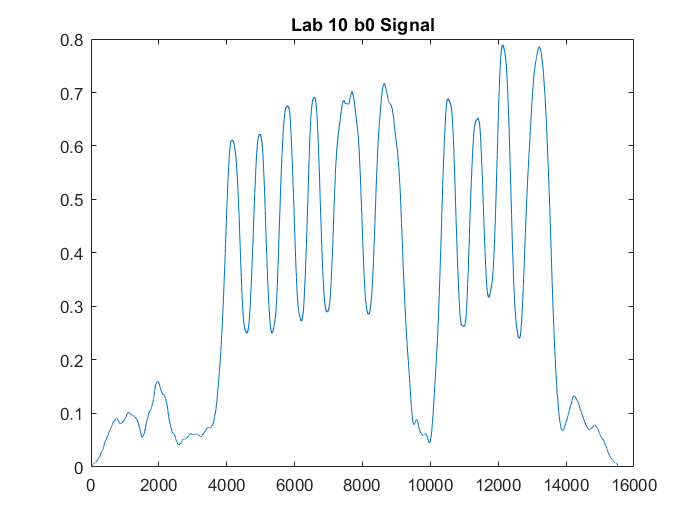

plot(b_0) 
title('Lab 10 b0 Signal')



%Matched Filter Design & Envelope Detector for s1
x_1 = conv(r,s1)*(2/Ns)

x_1 =          0
    0.0036
    0.0086
    0.0086
   -0.0002
   -0.0116
   -0.0195
   -0.0119
    0.0007
    0.0156


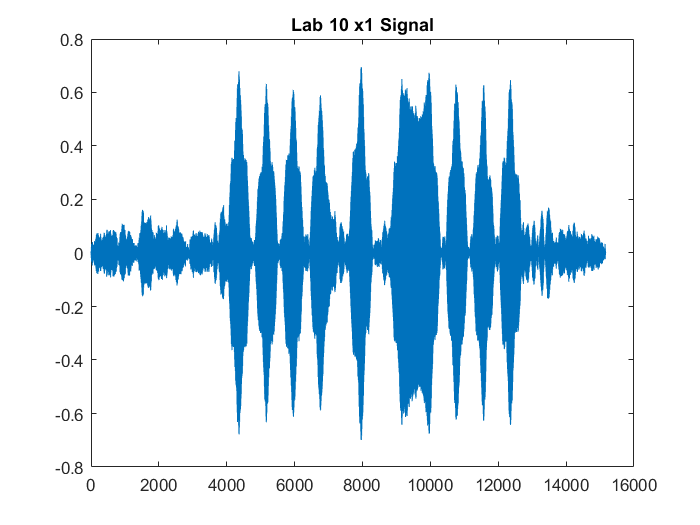

plot(x_1) %matched filter output
title('Lab 10 x1 Signal')

Ts = (Tb/Ns) % sample period

Ts = 2.5000e-04

%Envelope Detector 1:
y_1 = abs(x_1) %Rectify

y_1 =          0
    0.0036
    0.0086
    0.0086
    0.0002
    0.0116
    0.0195
    0.0119
    0.0007
    0.0156


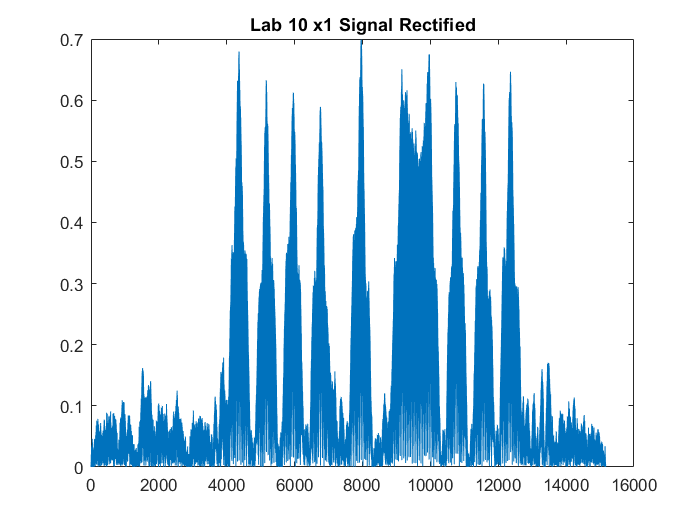

plot(y_1) %gives us positive half of matched filter output
title('Lab 10 x1 Signal Rectified')

%Lowpass Filter
b_1 = conv(y_1, ones(1,Ns))*(2/Ns)

b_1 =          0
    0.0000
    0.0001
    0.0001
    0.0001
    0.0002
    0.0003
    0.0003
    0.0003
    0.0004


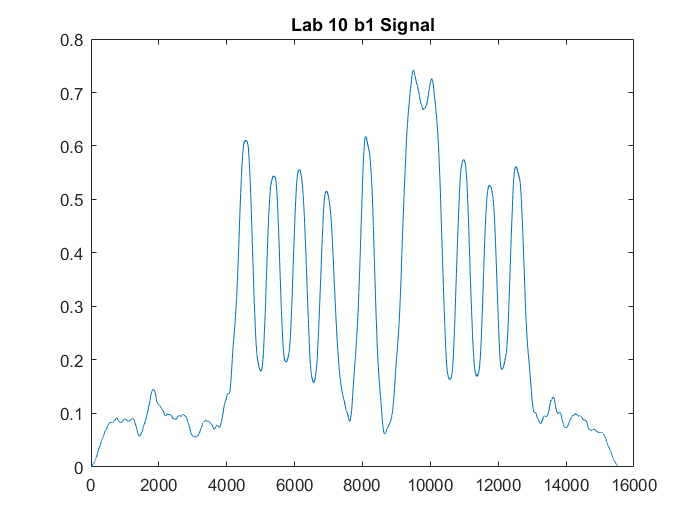

plot(b_1)
title('Lab 10 b1 Signal')

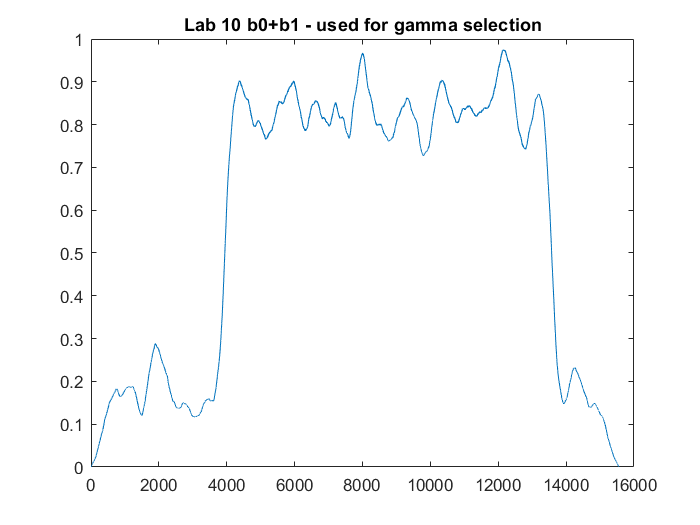


plot(b_0+b_1)
title('Lab 10 b0+b1 - used for gamma selection')


%Summation of both signals
b_0 = (-1*b_0)

b_0 =          0
   -0.0000
   -0.0001
   -0.0001
   -0.0001
   -0.0002
   -0.0003
   -0.0003
   -0.0003
   -0.0004


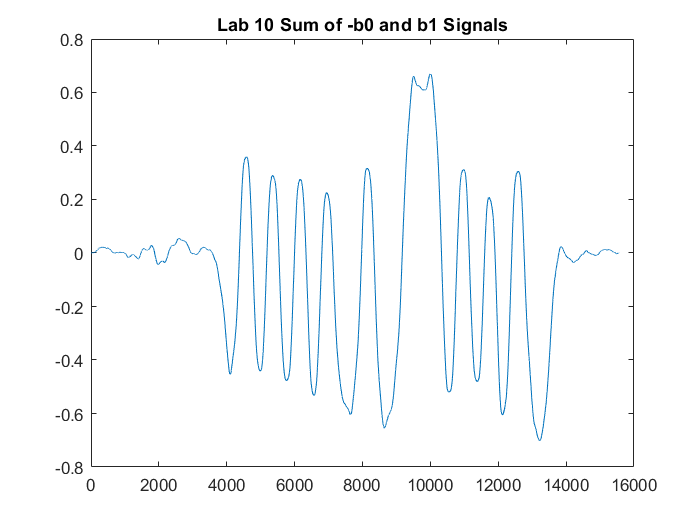

sum_b0_b1 = b_0 + b_1;
plot(sum_b0_b1)
title('Lab 10 Sum of -b0 and b1 Signals')



%Bit Synchronization for bit switch
gamma = 0.2 %threshold set experimental value

gamma = 0.2000

index = 1 

index = 1

while( abs((b_0(index) + b_1(index))) < gamma) %loop to count (b0+b1)(t) to greater than gamma 
index = index+1; %increase the index of b0 and b1 by 1 
end
t0 = index % length of the noise from 0 to when the synch bits start

t0 = 3895


[y, I] = max(b_0(t0:t0+Ns))

y = -0.3030

I = 1

Ts = I + t0 - 1 % synch time for the sampler 

Ts = 3895

synch = [sum_b0_b1(Ts) sum_b0_b1(Ts+Ns) sum_b0_b1(Ts+(2*Ns)) sum_b0_b1(Ts+(3*Ns)) sum_b0_b1(Ts+(4*Ns)) sum_b0_b1(Ts+(5*Ns)) sum_b0_b1(Ts+(6*Ns)) sum_b0_b1(Ts+(7*Ns))]

synch =    -0.2003   -0.2351    0.2199   -0.3124    0.1426   -0.3534    0.1215   -0.3674



%sampling the data 
data = [];
for k = 1:24 %going through the first 24 bits: 8 synch bits and 16 data bits
    data = [data sum_b0_b1(Ts+k*Ns)];
end
data

data =    -0.2351    0.2199   -0.3124    0.1426   -0.3534    0.1215   -0.3674    0.0688   -0.5669   -0.2665    0.1472   -0.6403   -0.2439    0.6589    0.6202    0.1270   -0.3525    0.1706   -0.3620    0.0260   -0.4045    0.2012   -0.6524   -0.4179



%Quantization of data (takes care of sign and level shifting)
for j = 1:length(data)
    if (data(j) > 0) %if analog data is pos, set it to 1
       quant_data(j) = 1;
    else  
       quant_data(j) = 0;
    end
end
quant_data

quant_data =      0     1     0     1     0     1     0     1     0     0     1     0     0     1     1     1     0     1     0     1     0     1     0     0


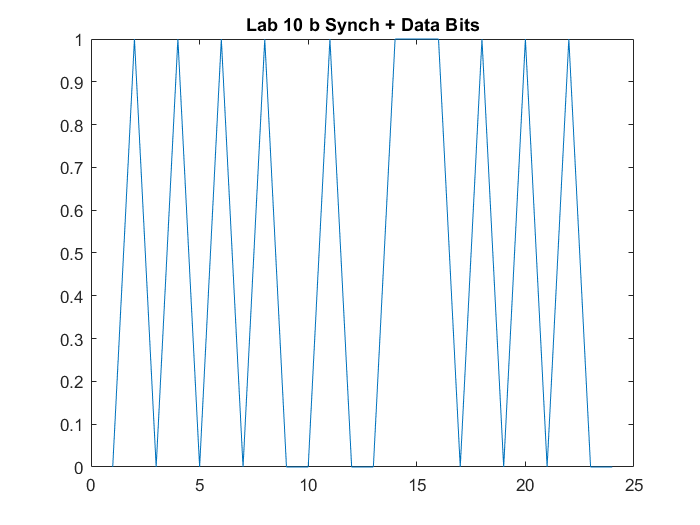

plot(quant_data)
title('Lab 10 b Synch + Data Bits')

I'm sure this is correct because the first 8 synch bits are 01 repeating, given the **gamma(threshold)** that has been experimentally set to **0.2.** 

After that, the data pattern follows for 16 bits.